clear all;
close all;

dt = 0.25; % Time step

% Sattelite inertial parameters
m = 4;
w = 0.1;
d = 0.1;
h = 0.3;
Ix = (1/12)*m*(w^2+h^2);
Iy = (1/12)*m*(d^2+h^2);
Iz = (1/12)*m*(w^2+d^2);
I = [Ix, 0, 0; 0, Iy, 0; 0, 0, Iz]; % Inertia tensor used in estimations

We initiallise the system rotating at a very high angular velocity, at an arbitrary attitude. The P matrix is initiallize to be the zero matrix.


% Initial conditions
P0 = zeros(7);
x0_hat = ones(7,1);
x0_hat(1) = -7.8;
x0_hat(2) = 10.6;
x0_hat(3) = 6.1;
x0_hat(4) = 0.7;
x0_hat(5) = -0.4;
x0_hat(6) = -0.6;
x0_hat(7) = 0.2;
x0_hat(4:7) = x0_hat(4:7) ./ norm(x0_hat(4:7));

target = [-7;4;3;-7];
target = target/norm(target);

x_true = x0_hat;
Pk = P0;

u = [0; 0; 0];
M = u;


The model of the dynamis which we use to estimate the state of the satellite is only an approximate estimate so we assume a certain normal distributed random variation, from this random variation we determine the covariance matrix Q which we assume to be a diagonal matrix we a certain variance of each component of the state.


% Process noise and covariance matrices
eta = 1E-4;
zeta = 1E-4;
omegaDotVar = (eta/2)^2;
qDotVar = (zeta/2)^2;
procVar(1:3) = omegaDotVar .* ones(3,1);
procVar(4:7) = qDotVar .* ones(4,1);
Q0 = diag(procVar);
H = eye(7);

% Measurement noise
delta = 0.5;
gyroVar = (pi*delta/360)^2;

epsilon = 1E-1;
qVar = (epsilon/2)^2;


obsVar(1:3) = gyroVar .* ones(3,1);
obsVar(4:7) = qVar .* ones(4,1);
R = diag(obsVar);

pred = @prediction;
upd = @update;
new_true = @next_true;

% Functions

Om = @(omega) [0, omega(3), -omega(2), omega(1);
               -omega(3), 0, omega(1), omega(2);
               omega(2), -omega(1), 0, omega(3);
               -omega(1), -omega(2), -omega(3), 0];

quaternion_multiply = @(a,b) [a(1)*b(1)-a(2)*b(2)-a(3)*b(3)-a(4)*b(4);
                                a(1)*b(2)+a(2)*b(1)+a(3)*b(4)-a(4)*b(3);
                                a(1)*b(3)-a(2)*b(4)+a(3)*b(2)+a(4)*b(2);
                                a(1)*b(4)+a(2)*b(3)-a(3)*b(2)+a(4)*b(1)];
            

quat_to_euler = @(q) [atan2(2*(q(1)*q(2)+q(3)*q(4)),1-2*(q(2)^2+q(3)^2));
                      asin(2*(q(1)*q(3)-q(4)*q(2)));
                      atan2(2*(q(1)*q(4)+q(2)*q(3)),1-2*(q(3)^2+q(4)^2))];
                  
euler_to_quat = @(e) [cos(e(1)/2)*cos(e(2)/2)*cos(e(3)/2)+sin(e(1)/2)*sin(e(2)/2)*sin(e(3)/2);
                      sin(e(1)/2)*cos(e(2)/2)*cos(e(3)/2)-cos(e(1)/2)*sin(e(2)/2)*sin(e(3)/2);
                      cos(e(1)/2)*sin(e(2)/2)*cos(e(3)/2)+sin(e(1)/2)*cos(e(2)/2)*sin(e(3)/2);
                      cos(e(1)/2)*cos(e(2)/2)*sin(e(3)/2)-sin(e(1)/2)*sin(e(2)/2)*cos(e(3)/2)];

quat_to_matrix = @(q) [1-2*(q(3)^2+q(4)^2), 2*(q(2)*q(3)-q(4)*q(1)), 2*(q(2)*q(4)+q(3)*q(1));
                       2*(q(2)*q(3)+q(4)*q(1)), 1-2*(q(2)^2+q(4)^2), 2*(q(3)*q(4)-q(2)*q(1));
                       2*(q(2)*q(4)-q(3)*q(1)), 2*(q(3)*q(4)+q(2)*q(1)), 1-2*(q(2)^2+q(3)^2)];

 euler_to_matrix = @(e) [1,0,0; 0,cos(e(1)),-sin(e(1)); 0,sin(e(1)),cos(e(1))]*[cos(e(2)),0,sin(e(2)); 0,1,0; -sin(e(2)),0,cos(e(2))]*[cos(e(3)),-sin(e(3)),0; sin(e(3)),cos(e(3)),0; 0,0,1];
 
cal_jaco = @calc_jacobian;

N = 50000; % Number of Time Steps

% Result Data Lists
w_list = zeros(N,3);
q_list = zeros(N,4);
x_true_list = zeros(N,7);
z_list = zeros(N,7);
speed_list = zeros(N,1);
true_speed_list = zeros(N,1);
torque_list = zeros(N,1);
err_list = zeros(N,1);
t_list = zeros(N,1);

% Random observation noise
errq = randn*sqrt(qVar);
errw = randn*sqrt(gyroVar);
z = x_true + [randn*sqrt(gyroVar);randn*sqrt(gyroVar);randn*sqrt(gyroVar);randn*sqrt(qVar);randn*sqrt(qVar);randn*sqrt(qVar);randn*sqrt(qVar)]; % Initial measurement
xk = z; % Use first measurement as first data point


% PID parameters

K_p = 0.1;
K_i = 0.4;
K_d = 0.08;
SP = [0.0;0.0;0.0]; % Want 0 angular velocity
q = xk(4:7);
att = quat_to_euler(q);
omega = xk(1:3);
PV = omega;
e_p = SP - PV;
e_n = SP - PV;
a = 0;
In = [0; 0; 0];
                           

Here we implement a loop in which each time step we update the true value of the sattelite state, then take measurements of these values with random sensor noise and using these we estimate the state of the satellite. With this estimate we use a PID controller to determine the desired torque on the satellite to achieve the desired angular velocity.


for k=1:N    
    % Random process noise
    errqDot = randn*sqrt(qDotVar);
    errwDot = randn*sqrt(omegaDotVar);    
    
            
    % Update true value with random noise
    x_true = new_true(I,dt,x_true,u) + [randn*sqrt(omegaDotVar);randn*sqrt(omegaDotVar);randn*sqrt(omegaDotVar);randn*sqrt(qDotVar);randn*sqrt(qDotVar);randn*sqrt(qDotVar);randn*sqrt(qDotVar)];
    x_true(4:7) = x_true(4:7)/norm(x_true(4:7)); % Normalize
        
    

The data which the satellite measures has a high degree of noise so in order to more accurately determine the state of the satellite we use a method called a Kalman filter.

The Kalman filter uses a previous estimate of the state of the sattelite and an approximate model of the sattelite dynamics to predict the current state of the sattelite. However, the model of the dynamics has a significant level of error so we cannot use this prediction alone.

We also have measured values of the state with their own random distribution, a more accurate estimate of the state can be determined by combining the two probability distributions created by these two estimates. They are combined using the following formula


$$x_k = \hat{x}_k + K_k(z - \hat{x}_k)$$


Where $\hat{x}_k$ is the predicted value, z is the measured value and $K_k$ is known as the Kalman gain calculated using the following formula


$$K_k = \hat{P}_k H (H\hat{P}_kH^T + R)$$


This represents the degree to which we trust the measured values versus the predicted values.

This new combined estimate can then be used to predict the next value and over time these estimates will converge to an optimal estimate of the state of the sattelite.

    
    % Kalman Filter
    % Adjust Covariance to prevent numerical instability
    
    

The kalman filter has numerical instability. When the angular velocity becomes too high the filter will attempt to invert a nearly singular matrix, which will cause the results to be highly innacurate. To prevent this, we can increase the variance in the process proportionately to the angular speed when this speed is high.

    if norm(omega) > 1
        Q = Q0*norm(omega);
    else
        Q = Q0;
    end
    
    F = real(cal_jaco(xk,I,dt)); % Update Jacobian Matrix
    % Random observation noise
    errq = randn*sqrt(qVar);
    errw = randn*sqrt(gyroVar);
    z = x_true + [randn*sqrt(gyroVar);randn*sqrt(gyroVar);randn*sqrt(gyroVar);randn*sqrt(qVar);randn*sqrt(qVar);randn*sqrt(qVar);randn*sqrt(qVar)]; % Measurement
    [xhat_pred, P_pred] = pred(I,dt,Q,xk,u,F,Pk); % Predict next value from previous
    [xk,Pk] = update(H, xhat_pred, P_pred, z, R); % Update using measured value
    xk(4:7) = xk(4:7)/norm(xk(4:7)); % Renormalize quaternion
    
    

Here we must determine the desired angular velocity with which we wish to have the satellite rotate in order to move from its current attitude to the desired target attitude. Let $\vec{p}$ be the target attitude quaternion and $\vec{q}$ the current attitude then we wish to find some angular velocity $\vec{\omega}$ satisfying


$$\vec{p} \propto \frac{1}{2}\omega \vec{q}\Delta t + \vec{q} = \frac{1}{2}\pmatrix{1 & -\omega_x\Delta t & -\omega_y\Delta t & -\omega_z\Delta t \cr \omega_x\Delta t & 1 & -\omega_z\Delta t & \omega_y\Delta t \cr \omega_y\Delta t & \omega_z\Delta t & 1 & -\omega_x\Delta t \cr \omega_z\Delta t & -\omega_y\Delta t & \omega_x\Delta t & 1}\vec{q}$$


So introduce a free variable c and we have


$$\vec{p} = c\cdot \frac{1}{2}\pmatrix{1 & -\omega_x\Delta t & -\omega_y\Delta t & -\omega_z\Delta t \cr \omega_x\Delta t & 1 & -\omega_z\Delta t & \omega_y\Delta t \cr \omega_y\Delta t & \omega_z\Delta t & 1 & -\omega_x\Delta t \cr \omega_z\Delta t & -\omega_y\Delta t & \omega_x\Delta t & 1}\vec{q}$$


This is a system of 4 linear equations in 4 unknowns so is easily solved for the variables $\omega_x,\omega_y,\omega_z,c$ as


$$\omega_x = -(p_1q_2 - p_2q_1 + p_3q_4 - p_4q_3)/(\Delta t\cdot (p_1q_1 + p_2q_2 + p_3q_3 + p_4q_4))$$



$$\omega_y = -(p_1q_3 - p_2q_4 - p_3q_1 + p_4q_2)/(\Delta t\cdot (p_1q_1 + p_2q_2 + p_3q_3 + p_4q_4))$$



$$\omega_z = -(p_1q_4 + p_2q_3 - p_3q_2 - p_4q_1)/(\Delta t\cdot (p_1q_1 + p_2q_2 + p_3q_3 + p_4q_4))$$



$$c = (p_1q_1 + p_2q_2 + p_3q_3 + p_4q_4)/(q_1^2 + q_2^2 + q_3^2 + q_4^2)$$


Since these are unit quaternions the magnitude is devided out so c can be freely ignored thus we can have the solution


$$\vec{\omega} = \pmatrix{\omega_x \cr \omega_y \cr \omega_z}$$


We set the target angular velocity to be 1/100 of this angular velocity so the satellite will slowly rotate toward the desired attitude

    % PID
    q = xk(4:7);
    att = quat_to_euler(q);
    omega = xk(1:3);
    p = target;
    
    T = dt;
    
    q_1 = q(1);
    q_2 = q(2);
    q_3 = q(3);
    q_4 = q(4);
    
    p_1 = p(1);
    p_2 = p(2);
    p_3 = p(3);
    p_4 = p(4);
    
    w_1 = (-(p_1*q_2 - p_2*q_1 + p_3*q_4 - p_4*q_3)/(T*(p_1*q_1 + p_2*q_2 + p_3*q_3 + p_4*q_4)));
    w_2 = -(p_1*q_3 - p_2*q_4 - p_3*q_1 + p_4*q_2)/(T*(p_1*q_1 + p_2*q_2 + p_3*q_3 + p_4*q_4));
    w_3 = -(p_1*q_4 + p_2*q_3 - p_3*q_2 - p_4*q_1)/(T*(p_1*q_1 + p_2*q_2 + p_3*q_3 + p_4*q_4));
    
    ww = [w_1;w_2;w_3];
    
    qinv = [q(1);-q(2);-q(3);-q(4)];
    wb1 = quat_mult(qinv,quat_mult([0;ww],q));
    wb = wb1(2:4);
    
    SP = wb/100;
    

The system operates with a PID controller, which stands for Proportional, Integral, Derivative. This controller determines the desired acceleration and torque of the sattelite given the current angular velocity as the sum of three terms, which are a constant multiple of the error from the desired value, the integral of this error over time and the derivative of this error in time. In the proportional term, the previous values stored in the integral term, and the prediction of future behaviour from the derivative term using the formula


$$a = K_p e(t) + K_i \int_{t_0}^t e(\tau)d\tau + K_d\frac{d e}{dt}$$


Where e(t) is the error between the current process value PV and the desired set point SP, so is in this case equal to the angular velocity of the sattelite. K_p, K_i, K_d represent the strengths of the proportional, integral, and derivative terms respectively.

By using the integral term long terms sustained error will build up the strength of the control so the desired torque will increase the longer the error persists.

The derivative term allows the controller to predict the future behaviour of the sattelite reducing the tendency of the controller to overshoot the desired values.

    PV = omega;
    e_p = e_n; % Error at previous time
    e_n = SP - PV; % Error at current time
    
    In = In+(1/2)*(e_p+e_n)*dt; % Update integral using trapezoidal method
    
    % Remove integral when passing zero error to reduce overshoot
    
    if e_n(1)*In(1) < 0
        In(1) = 0;
    end
    if e_n(2)*In(2) < 0
        In(2) = 0;
    end
    if e_n(3)*In(3) < 0
        In(3) = 0;
    end
        
    a = K_p*e_n + K_i*In + K_d*(e_p-e_n)/dt; % Desired angular acceleration
    u = (I*a + cross(omega,(I*omega)))/100; % Required torque to achieve desired acceleration
    
    % Store results in data lists
    w_list(k,:) = xk(1:3);
    q_list(k,:) = xk(4:7);
    x_true_list(k,:) = x_true;
    z_list(k,:) = z;
    torque_list(k) = norm(u);
    true_speed_list(k) = norm(x_true(1:3));
    speed_list(k) = norm(omega);
    err_list(k) = norm((quat_to_euler(q)-quat_to_euler(target))*180/pi);
    t_list(k) = k*dt;
    
end

Here we create plots of the results of the simulation showing the speed and the attitude. From these we see that the speed will quickly be reduced to zero and the initially rapidly oscillating attitude will reach an approximately constant value, indicating that the sattelites rotation has stopped. We plot values of both the true state of the sattelite and the kalman filter estimated states and we can see that these values are very close and accurate estimates.

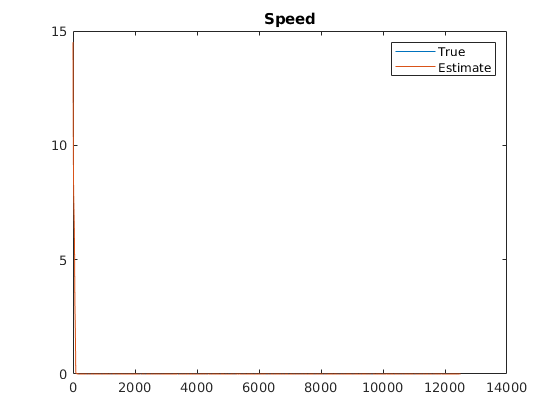

% Plot output
plot(t_list,true_speed_list,t_list,speed_list);
title('Speed');
legend('True','Estimate');

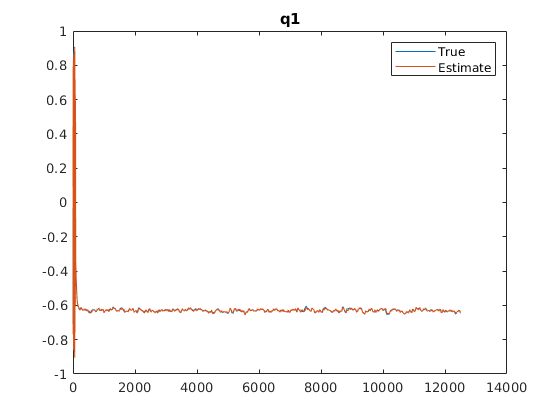

figure;
plot(t_list,x_true_list(:,4),t_list,q_list(:,1));
legend('True','Estimate');
title('q1');

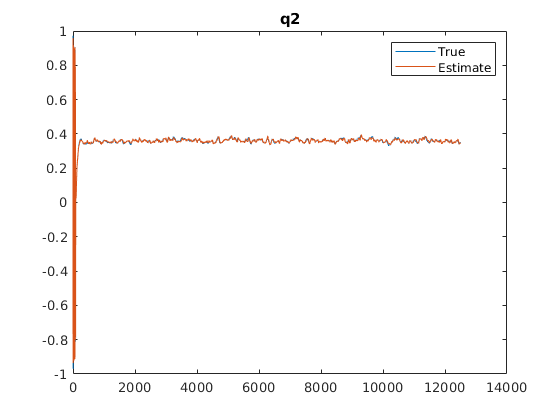

figure;
plot(t_list,x_true_list(:,5),t_list,q_list(:,2));
legend('True','Estimate');
title('q2');

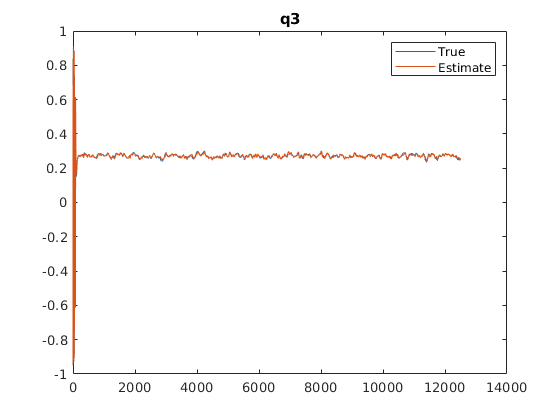

figure;
plot(t_list,x_true_list(:,6),t_list,q_list(:,3));
legend('True','Estimate');
title('q3');

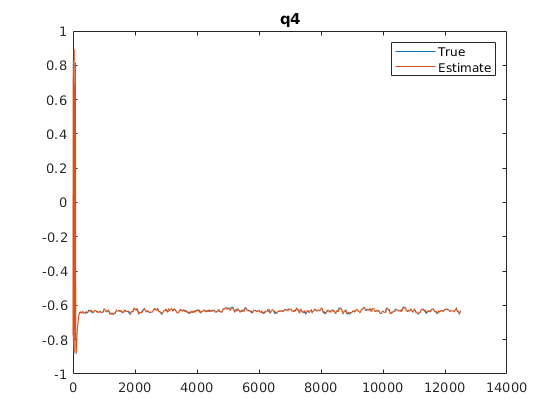

figure;
plot(t_list,x_true_list(:,7),t_list,q_list(:,4));
legend('True','Estimate');
title('q4');

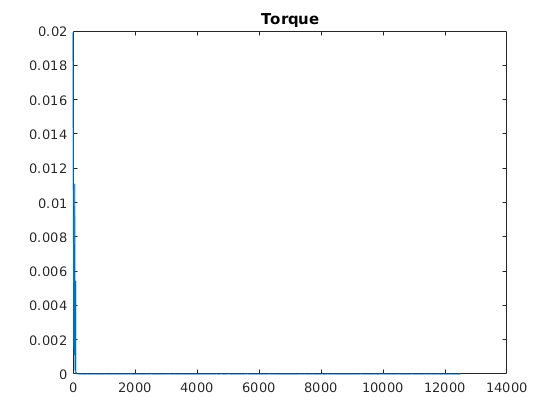

figure
plot(t_list,torque_list);
title('Torque');

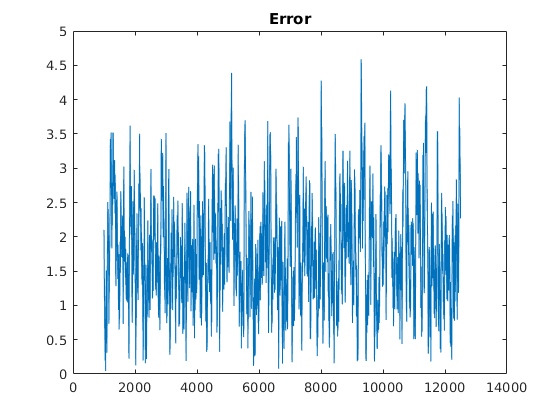

figure
plot(t_list(4000:end),err_list(4000:end));
title('Error');

The following functions are responsible for converting between the three different representations of attitudes: quaternions, euler angles and rotation matricies

function M = e_to_mat(e)
M = [1,0,0; 0,cos(e(1)),-sin(e(1)); 0,sin(e(1)),cos(e(1))]*[cos(e(2)),0,sin(e(2)); 0,1,0; -sin(e(2)),0,cos(e(2))]*[cos(e(3)),-sin(e(3)),0; sin(e(3)),cos(e(3)),0; 0,0,1];
end

function e = mat_to_e(M)
sy = sqrt(M(1,1)^2 + M(2,1)^2);
singular = sy<1E-6;

if not(singular)
    x = atan2(M(3,2),M(3,3));
    y = atan2(-M(3,1),sy);
    z = atan2(M(2,1),M(1,1));
else
    x = atan2(-M(2,3),M(2,2));
    y = atan2(-M(3,1),sy);
    z = 0
end
e = [x;y;z];
end

function q = e_to_quat(e)
q = [cos(e(1)/2)*cos(e(2)/2)*cos(e(3)/2)+sin(e(1)/2)*sin(e(2)/2)*sin(e(3)/2);
    sin(e(1)/2)*cos(e(2)/2)*cos(e(3)/2)-cos(e(1)/2)*sin(e(2)/2)*sin(e(3)/2);
    cos(e(1)/2)*sin(e(2)/2)*cos(e(3)/2)+sin(e(1)/2)*cos(e(2)/2)*sin(e(3)/2);
    cos(e(1)/2)*cos(e(2)/2)*sin(e(3)/2)-sin(e(1)/2)*sin(e(2)/2)*cos(e(3)/2)];
end

function e = quat_to_e(q)
e = [atan2(2*(q(1)*q(2)+q(3)*q(4)),1-2*(q(2)^2+q(3)^2));
    asin(2*(q(1)*q(3)-q(4)*q(2)));
    atan2(2*(q(1)*q(4)+q(2)*q(3)),1-2*(q(3)^2+q(4)^2))];
end

This function performs the multiplication of two quaternions

function q = quat_mult(a,b)
q = [a(1)*b(1)-a(2)*b(2)-a(3)*b(3)-a(4)*b(4);
    a(1)*b(2)+a(2)*b(1)+a(3)*b(4)-a(4)*b(3);
    a(1)*b(3)-a(2)*b(4)+a(3)*b(1)+a(4)*b(2);
    a(1)*b(4)+a(2)*b(3)-a(3)*b(2)+a(4)*b(1)];
end


This function updates the true value of the satellite attitude and angular velocity, using euler's rotation equations. These give us differential equations which can be solved for the current value of the attitude and angular velocity. The equation for the attitude is


$$\vec{\dot{q}} = \frac{1}{2}\vec\omega\vec{q}$$


Where $\omega$ is considered as a quaternion with zero scalar part. This can also be represented with a matrix as


$$$$\vec{\dot{q}} = \frac{1}{2}\Omega(\vec\omega)\vec{q}$$$$


Where


$$\Omega(\vec{\omega}) = \pmatrix{0 & -\omega_x & -\omega_y & -\omega_z \cr \omega_x & 0 & -\omega_z & \omega_y \cr \omega_y & \omega_z & 0 & -\omega_x \cr \omega_z & -\omega_y & \omega_x & 0}$$


is the matrix representation of the linear operation of multiplication by $\omega$

This gives a solution of


$$\vec{q}(t) = e^{\frac{1}{2}\Omega(\vec\omega)\Delta t}\vec{q}_0$$


The angular velocity can be solved as a function of the angular acceleration satisfies the differential equation


$$\vec{\dot{\omega}} = I^{-1}\vec{u}-I^{-1}(\vec{\omega}\times I\vec{\omega})$$


Given the symmetries in the inertia of the sattelite which result from its shape, within the body reference frame the inertia tensor can be represented as


$$I = \pmatrix{I_x & 0 & 0\cr 0 & I_y & 0\cr 0 & 0 & I_z}$$


with $I_x=I_y$

Therefore the equation becomes


$$\vec{\dot{\omega}} = \pmatrix{1/I_x & 0 & 0\cr 0 & 1/I_y & 0\cr 0 & 0 & 1/I_z}\pmatrix{u_1\cr u_2\cr u_3} - \pmatrix{1/I_x & 0 & 0\cr 0 & 1/I_y & 0\cr 0 & 0 & 1/I_z}\left(\pmatrix{\omega_x\cr \omega_y\cr \omega_z}\times\pmatrix{I_x\omega_x\cr I_y\omega_z\cr I_z\omega_z}\right)$$



$$= \pmatrix{u_1/I_x\cr u_2/I_y\cr u_3/I_z} - \pmatrix{\omega_y\omega_z\cdot (I_z-I_y)/I_x\cr \omega_x\omega_z\cdot (I_x-I_z)/I_y\cr \omega_x\omega_y\cdot (I_y-I_x)/I_z}

= \pmatrix{\omega_y\omega_z\cdot (I_y-I_z)/I_x\cr \omega_x\omega_z\cdot (I_z-I_x)/I_y\cr 0} +  \pmatrix{u_1/I_x\cr u_2/I_y\cr u_3/I_z}$$


We can solve the homogenous part of this system of equations in the body reference frame as the following


$$\omega(t) = \pmatrix{\frac{1}{2}\cdot c_2\cdot \exp(-\sqrt{ab}\cdot c_1\cdot t)\cdot (\exp(2\sqrt{ab}\cdot c_1\cdot t)+1) + c_3\cdot \sqrt{a}\cdot \exp(-\sqrt{ab}\cdot c_1\cdot t)*(\exp(2\cdot \sqrt{ab}\cdot c_1\cdot t)-1)/(2\sqrt{b}) \cr
\frac{1}{2}\cdot c_3\cdot \exp(-\sqrt{ab}\cdot c_1\cdot t)\cdot (\exp(2\sqrt{ab}\cdot c_1\cdot t)+1) + c_2\cdot \sqrt{b}\cdot \exp(-\sqrt{ab}\cdot c_1\cdot t)\cdot (\exp(2\sqrt{ab}\cdot c_1\cdot t)-1)/(2\sqrt{a}) \cr
c_1}$$


Where


$$c_1 = \omega_z(0), \ c_2 = \omega_x(0), \ c_3 = \omega_y(0)$$



$$a = (I_y-I_z)/I_x$$



$$b = (I_z-I_x)/I_y$$


Thus, approximating the forcing term using Euler's method, we can discretize this into


$$\vec{\omega}^b_k = \pmatrix{\frac{1}{2}\cdot c_2\cdot \exp(-\sqrt{ab}\cdot c_1\cdot \Delta t)\cdot (\exp(2\sqrt{ab}\cdot c_1\cdot \Delta t)+1) + c_3\cdot \sqrt{a}\cdot \exp(-\sqrt{ab}\cdot c_1\cdot \Delta t)*(\exp(2\sqrt{ab}\cdot c_1\cdot \Delta t)-1)/(2\sqrt{b}) + u_1\cdot \Delta t/I_{1,1} \cr
\frac{1}{2}\cdot c_3\cdot \exp(-\sqrt{ab}\cdot c_1\cdot \Delta t)\cdot (\exp(2\sqrt{ab}\cdot c_1\cdot \Delta t)+1) + c_2\cdot \sqrt{b}\cdot \exp(-\sqrt{ab}\cdot c_1\cdot \Delta t)\cdot (\exp(2\sqrt{ab}\cdot c_1\cdot \Delta t)-1)/(2\sqrt{a}) + u_2\cdot \Delta t/I_{2,2} \cr
c_1+u_3\cdot \Delta t/I_{3,3}}$$



$$\vec{q}_k = e^{\frac{1}{2}\Omega(\vec{\omega}^w_{k-1})\Delta T}\vec{q}_{k-1}$$


Where $\vec{\omega}^b$ is the angular velocity in the body reference frame and $\vec{\omega}^w$ is the angular velocity in the world reference frame with the conversion


$$\vec{w}^w = \vec{q}\cdot \vec{w}^b\cdot \vec{q}^{-1}$$


% Calculate next true value of x
function x = next_true(I,T,x_prev,u_prev)
w_prev = x_prev(1:3);
q_prev = x_prev(4:7);
qinv = [q_prev(1);-q_prev(2);-q_prev(3);-q_prev(4)];
ww1 = quat_mult(q_prev,quat_mult([0;w_prev],qinv));
ww = ww1(2:4);
Omega = [0, -ww(1), -ww(2), -ww(3);
         ww(1), 0, -ww(3), ww(2);
         ww(2), ww(3), 0, -ww(1);
         ww(3), -ww(2), ww(1), 0];
c1 = x_prev(3);
c2 = x_prev(1);
c3 = x_prev(2);
a = (I(2,2)-I(3,3))/I(1,1);
b = (I(3,3)-I(1,1))/I(2,2);
wNext = real([(1/2)*c2*exp(-sqrt(a*b)*c1*T)*(exp(2*sqrt(a*b)*c1*T)+1) + c3*sqrt(a)*exp(-sqrt(a*b)*c1*T)*(exp(2*sqrt(a*b)*c1*T)-1)/(2*sqrt(b)) + u_prev(1)*T/I(1,1); (1/2)*c3*exp(-sqrt(a*b)*c1*T)*(exp(2*sqrt(a*b)*c1*T)+1) + c2*sqrt(b)*exp(-sqrt(a*b)*c1*T)*(exp(2*sqrt(a*b)*c1*T)-1)/(2*sqrt(a)) + u_prev(2)*T/I(2,2); c1+u_prev(3)*T/I(3,3)]);
qNext = expm(0.5 * Omega * T) * q_prev;
x = [wNext; qNext];
end

This function predicts the next value of the attitude and angular velocity given the previous value using the same rotation equations used above.

The function then predicts a new value of the P matrix using


$$P_{k+1} = FP_kF^T + Q$$


% Predict next x value from previous
function [xhat_pred, P_pred] = prediction(I,T,Q,xhat_prev,u_prev,F,P)
what_prev = xhat_prev(1:3);
qhat_prev = xhat_prev(4:7);
qinv = [qhat_prev(1);-qhat_prev(2);-qhat_prev(3);-qhat_prev(4)];
ww1 = quat_mult(qhat_prev,quat_mult([0;what_prev],qinv));
ww = ww1(2:4);
Omega = [0, -ww(1), -ww(2), -ww(3);
         ww(1), 0, -ww(3), ww(2);
         ww(2), ww(3), 0, -ww(1);
         ww(3), -ww(2), ww(1), 0];
     
c1 = xhat_prev(3);
c2 = xhat_prev(1);
c3 = xhat_prev(2);
a = (I(2,2)-I(3,3))/I(1,1);
b = (I(3,3)-I(1,1))/I(2,2);
wNext = real([(1/2)*c2*exp(-sqrt(a*b)*c1*T)*(exp(2*sqrt(a*b)*c1*T)+1) + c3*sqrt(a)*exp(-sqrt(a*b)*c1*T)*(exp(2*sqrt(a*b)*c1*T)-1)/(2*sqrt(b)) + u_prev(1)*T/I(1,1); (1/2)*c3*exp(-sqrt(a*b)*c1*T)*(exp(2*sqrt(a*b)*c1*T)+1) + c2*sqrt(b)*exp(-sqrt(a*b)*c1*T)*(exp(2*sqrt(a*b)*c1*T)-1)/(2*sqrt(a)) + u_prev(2)*T/I(2,2); c1+u_prev(3)*T/I(3,3)]);
qNext = expm(0.5 * Omega * T) * qhat_prev;
xhat_pred = [wNext; qNext];
P_pred = F * P * F' + Q;
end

Given the predict value xhat_pred and the measured value z of the state, this function combines these values into the most accurate estimate of the current state of the system using


$$x_k = \hat{x}_k + K_k(z - \hat{x}_k)$$


Where


$$K_k = \hat{P}_k H (H\hat{P}H^T + R)$$


Is the Kalman gain which represents how strongly we trust the measured value compared to the predicted value

% Update x value using predicted and measured
function [xk, Pk] = update(H, xhat_pred, P_pred, z, R)
y = z - xhat_pred;
S = H * P_pred * H' + R;
K = P_pred * H * S^-1;
xk = xhat_pred + K*y;
Pk = (eye(7) - K*H) * P_pred;
end

This function calculates the jacobian of the matrix F given the current value of the attitude and angular speed since the Kalman filter is only able to operate on linear models of the system's dynamics so we must linearize the model to this approximate form.

% Calculate the jacobian matrix
function j = calc_jacobian(x,I,T)
w1 = x(1);
w2 = x(2);
w3 = x(3);
q1 = x(4);
q2 = x(5);
q3 = x(6);
q4 = x(7);
I1_1 = I(1,1);
I1_2 = I(1,2);
I1_3 = I(1,3);
I2_1 = I(2,1);
I2_2 = I(2,2);
I2_3 = I(2,3);
I3_1 = I(3,1);
I3_2 = I(3,2);
I3_3 = I(3,3);

j = [                                                                                                                                                                                                                                                                                                                                                                                                                           1 - T*(((I1_2*I2_3 - I1_3*I2_2)*(2*I2_1*w1 - I1_1*w2 + I2_2*w2 + I2_3*w3))/(I1_1*I2_2*I3_3 - I1_1*I2_3*I3_2 - I1_2*I2_1*I3_3 + I1_2*I2_3*I3_1 + I1_3*I2_1*I3_2 - I1_3*I2_2*I3_1) - ((I2_2*I3_3 - I2_3*I3_2)*(I2_1*w3 - I3_1*w2))/(I1_1*I2_2*I3_3 - I1_1*I2_3*I3_2 - I1_2*I2_1*I3_3 + I1_2*I2_3*I3_1 + I1_3*I2_1*I3_2 - I1_3*I2_2*I3_1) + ((I1_2*I3_3 - I1_3*I3_2)*(2*I3_1*w1 - I1_1*w3 + I3_2*w2 + I3_3*w3))/(I1_1*I2_2*I3_3 - I1_1*I2_3*I3_2 - I1_2*I2_1*I3_3 + I1_2*I2_3*I3_1 + I1_3*I2_1*I3_2 - I1_3*I2_2*I3_1)),                                                                                                                                                                                                                                                                                                                                                                                                                               T*(((I1_2*I3_3 - I1_3*I3_2)*(I1_2*w3 - I3_2*w1))/(I1_1*I2_2*I3_3 - I1_1*I2_3*I3_2 - I1_2*I2_1*I3_3 + I1_2*I2_3*I3_1 + I1_3*I2_1*I3_2 - I1_3*I2_2*I3_1) + ((I1_2*I2_3 - I1_3*I2_2)*(I1_1*w1 + 2*I1_2*w2 + I1_3*w3 - I2_2*w1))/(I1_1*I2_2*I3_3 - I1_1*I2_3*I3_2 - I1_2*I2_1*I3_3 + I1_2*I2_3*I3_1 + I1_3*I2_1*I3_2 - I1_3*I2_2*I3_1) - ((I2_2*I3_3 - I2_3*I3_2)*(I3_1*w1 - I2_2*w3 + 2*I3_2*w2 + I3_3*w3))/(I1_1*I2_2*I3_3 - I1_1*I2_3*I3_2 - I1_2*I2_1*I3_3 + I1_2*I2_3*I3_1 + I1_3*I2_1*I3_2 - I1_3*I2_2*I3_1)),                                                                                                                                                                                                                                                                                                                                                                                                                               T*(((I1_2*I2_3 - I1_3*I2_2)*(I1_3*w2 - I2_3*w1))/(I1_1*I2_2*I3_3 - I1_1*I2_3*I3_2 - I1_2*I2_1*I3_3 + I1_2*I2_3*I3_1 + I1_3*I2_1*I3_2 - I1_3*I2_2*I3_1) + ((I1_2*I3_3 - I1_3*I3_2)*(I1_1*w1 + I1_2*w2 + 2*I1_3*w3 - I3_3*w1))/(I1_1*I2_2*I3_3 - I1_1*I2_3*I3_2 - I1_2*I2_1*I3_3 + I1_2*I2_3*I3_1 + I1_3*I2_1*I3_2 - I1_3*I2_2*I3_1) + ((I2_2*I3_3 - I2_3*I3_2)*(I2_1*w1 + I2_2*w2 + 2*I2_3*w3 - I3_3*w2))/(I1_1*I2_2*I3_3 - I1_1*I2_3*I3_2 - I1_2*I2_1*I3_3 + I1_2*I2_3*I3_1 + I1_3*I2_1*I3_2 - I1_3*I2_2*I3_1)),                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        0,                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                          0,                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                          0,                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                          0;
                                                                                                                                                                                                                                                                                                                                                                                                                               T*(((I1_1*I2_3 - I1_3*I2_1)*(2*I2_1*w1 - I1_1*w2 + I2_2*w2 + I2_3*w3))/(I1_1*I2_2*I3_3 - I1_1*I2_3*I3_2 - I1_2*I2_1*I3_3 + I1_2*I2_3*I3_1 + I1_3*I2_1*I3_2 - I1_3*I2_2*I3_1) - ((I2_1*I3_3 - I2_3*I3_1)*(I2_1*w3 - I3_1*w2))/(I1_1*I2_2*I3_3 - I1_1*I2_3*I3_2 - I1_2*I2_1*I3_3 + I1_2*I2_3*I3_1 + I1_3*I2_1*I3_2 - I1_3*I2_2*I3_1) + ((I1_1*I3_3 - I1_3*I3_1)*(2*I3_1*w1 - I1_1*w3 + I3_2*w2 + I3_3*w3))/(I1_1*I2_2*I3_3 - I1_1*I2_3*I3_2 - I1_2*I2_1*I3_3 + I1_2*I2_3*I3_1 + I1_3*I2_1*I3_2 - I1_3*I2_2*I3_1)),                                                                                                                                                                                                                                                                                                                                                                                                                           1 - T*(((I1_1*I3_3 - I1_3*I3_1)*(I1_2*w3 - I3_2*w1))/(I1_1*I2_2*I3_3 - I1_1*I2_3*I3_2 - I1_2*I2_1*I3_3 + I1_2*I2_3*I3_1 + I1_3*I2_1*I3_2 - I1_3*I2_2*I3_1) + ((I1_1*I2_3 - I1_3*I2_1)*(I1_1*w1 + 2*I1_2*w2 + I1_3*w3 - I2_2*w1))/(I1_1*I2_2*I3_3 - I1_1*I2_3*I3_2 - I1_2*I2_1*I3_3 + I1_2*I2_3*I3_1 + I1_3*I2_1*I3_2 - I1_3*I2_2*I3_1) - ((I2_1*I3_3 - I2_3*I3_1)*(I3_1*w1 - I2_2*w3 + 2*I3_2*w2 + I3_3*w3))/(I1_1*I2_2*I3_3 - I1_1*I2_3*I3_2 - I1_2*I2_1*I3_3 + I1_2*I2_3*I3_1 + I1_3*I2_1*I3_2 - I1_3*I2_2*I3_1)),                                                                                                                                                                                                                                                                                                                                                                                                                              -T*(((I1_1*I2_3 - I1_3*I2_1)*(I1_3*w2 - I2_3*w1))/(I1_1*I2_2*I3_3 - I1_1*I2_3*I3_2 - I1_2*I2_1*I3_3 + I1_2*I2_3*I3_1 + I1_3*I2_1*I3_2 - I1_3*I2_2*I3_1) + ((I1_1*I3_3 - I1_3*I3_1)*(I1_1*w1 + I1_2*w2 + 2*I1_3*w3 - I3_3*w1))/(I1_1*I2_2*I3_3 - I1_1*I2_3*I3_2 - I1_2*I2_1*I3_3 + I1_2*I2_3*I3_1 + I1_3*I2_1*I3_2 - I1_3*I2_2*I3_1) + ((I2_1*I3_3 - I2_3*I3_1)*(I2_1*w1 + I2_2*w2 + 2*I2_3*w3 - I3_3*w2))/(I1_1*I2_2*I3_3 - I1_1*I2_3*I3_2 - I1_2*I2_1*I3_3 + I1_2*I2_3*I3_1 + I1_3*I2_1*I3_2 - I1_3*I2_2*I3_1)),                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        0,                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                          0,                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                          0,                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                          0;
                                                                                                                                                                                                                                                                                                                                                                                                                              -T*(((I1_1*I2_2 - I1_2*I2_1)*(2*I2_1*w1 - I1_1*w2 + I2_2*w2 + I2_3*w3))/(I1_1*I2_2*I3_3 - I1_1*I2_3*I3_2 - I1_2*I2_1*I3_3 + I1_2*I2_3*I3_1 + I1_3*I2_1*I3_2 - I1_3*I2_2*I3_1) - ((I2_1*I3_2 - I2_2*I3_1)*(I2_1*w3 - I3_1*w2))/(I1_1*I2_2*I3_3 - I1_1*I2_3*I3_2 - I1_2*I2_1*I3_3 + I1_2*I2_3*I3_1 + I1_3*I2_1*I3_2 - I1_3*I2_2*I3_1) + ((I1_1*I3_2 - I1_2*I3_1)*(2*I3_1*w1 - I1_1*w3 + I3_2*w2 + I3_3*w3))/(I1_1*I2_2*I3_3 - I1_1*I2_3*I3_2 - I1_2*I2_1*I3_3 + I1_2*I2_3*I3_1 + I1_3*I2_1*I3_2 - I1_3*I2_2*I3_1)),                                                                                                                                                                                                                                                                                                                                                                                                                               T*(((I1_1*I3_2 - I1_2*I3_1)*(I1_2*w3 - I3_2*w1))/(I1_1*I2_2*I3_3 - I1_1*I2_3*I3_2 - I1_2*I2_1*I3_3 + I1_2*I2_3*I3_1 + I1_3*I2_1*I3_2 - I1_3*I2_2*I3_1) + ((I1_1*I2_2 - I1_2*I2_1)*(I1_1*w1 + 2*I1_2*w2 + I1_3*w3 - I2_2*w1))/(I1_1*I2_2*I3_3 - I1_1*I2_3*I3_2 - I1_2*I2_1*I3_3 + I1_2*I2_3*I3_1 + I1_3*I2_1*I3_2 - I1_3*I2_2*I3_1) - ((I2_1*I3_2 - I2_2*I3_1)*(I3_1*w1 - I2_2*w3 + 2*I3_2*w2 + I3_3*w3))/(I1_1*I2_2*I3_3 - I1_1*I2_3*I3_2 - I1_2*I2_1*I3_3 + I1_2*I2_3*I3_1 + I1_3*I2_1*I3_2 - I1_3*I2_2*I3_1)),                                                                                                                                                                                                                                                                                                                                                                                                                           T*(((I1_1*I2_2 - I1_2*I2_1)*(I1_3*w2 - I2_3*w1))/(I1_1*I2_2*I3_3 - I1_1*I2_3*I3_2 - I1_2*I2_1*I3_3 + I1_2*I2_3*I3_1 + I1_3*I2_1*I3_2 - I1_3*I2_2*I3_1) + ((I1_1*I3_2 - I1_2*I3_1)*(I1_1*w1 + I1_2*w2 + 2*I1_3*w3 - I3_3*w1))/(I1_1*I2_2*I3_3 - I1_1*I2_3*I3_2 - I1_2*I2_1*I3_3 + I1_2*I2_3*I3_1 + I1_3*I2_1*I3_2 - I1_3*I2_2*I3_1) + ((I2_1*I3_2 - I2_2*I3_1)*(I2_1*w1 + I2_2*w2 + 2*I2_3*w3 - I3_3*w2))/(I1_1*I2_2*I3_3 - I1_1*I2_3*I3_2 - I1_2*I2_1*I3_3 + I1_2*I2_3*I3_1 + I1_3*I2_1*I3_2 - I1_3*I2_2*I3_1)) + 1,                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        0,                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                          0,                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                          0,                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                          0;
 - (T*q2)/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(1/2)) - ((q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*(T*q1*abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*sign(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2)) - T*q3*abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*sign(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2)) - T*q2*abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*sign(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2)) + T*q4*abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*sign(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))))/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(3/2)), - (T*q3)/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(1/2)) - ((q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*(T*q1*abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*sign(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2)) + T*q2*abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*sign(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2)) - T*q4*abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*sign(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2)) - T*q3*abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*sign(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))))/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(3/2)), - (T*q4)/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(1/2)) - ((q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*(T*q1*abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*sign(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2)) - T*q2*abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*sign(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2)) + T*q3*abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*sign(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2)) - T*q4*abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*sign(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))))/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(3/2)),          1/(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(1/2) - ((q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*(2*abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*sign(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2)) + T*w1*abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*sign(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2)) + T*w2*abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*sign(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2)) + T*w3*abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*sign(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))))/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(3/2)), - ((q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*(2*abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*sign(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2)) + T*w2*abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*sign(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2)) - T*w1*abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*sign(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2)) - T*w3*abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*sign(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))))/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(3/2)) - (T*w1)/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(1/2)), - ((q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*(2*abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*sign(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2)) - T*w1*abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*sign(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2)) + T*w3*abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*sign(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2)) - T*w2*abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*sign(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))))/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(3/2)) - (T*w2)/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(1/2)), - ((q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*(2*abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*sign(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2)) + T*w1*abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*sign(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2)) - T*w2*abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*sign(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2)) - T*w3*abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*sign(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))))/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(3/2)) - (T*w3)/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(1/2));
   (T*q1)/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(1/2)) - ((q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*(T*q1*abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*sign(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2)) - T*q3*abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*sign(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2)) - T*q2*abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*sign(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2)) + T*q4*abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*sign(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))))/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(3/2)), - (T*q4)/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(1/2)) - ((q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*(T*q1*abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*sign(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2)) + T*q2*abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*sign(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2)) - T*q4*abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*sign(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2)) - T*q3*abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*sign(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))))/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(3/2)),   (T*q3)/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(1/2)) - ((q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*(T*q1*abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*sign(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2)) - T*q2*abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*sign(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2)) + T*q3*abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*sign(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2)) - T*q4*abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*sign(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))))/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(3/2)), (T*w1)/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(1/2)) - ((q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*(2*abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*sign(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2)) + T*w1*abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*sign(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2)) + T*w2*abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*sign(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2)) + T*w3*abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*sign(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))))/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(3/2)),            1/(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(1/2) - ((q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*(2*abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*sign(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2)) + T*w2*abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*sign(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2)) - T*w1*abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*sign(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2)) - T*w3*abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*sign(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))))/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(3/2)),   (T*w3)/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(1/2)) - ((q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*(2*abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*sign(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2)) - T*w1*abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*sign(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2)) + T*w3*abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*sign(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2)) - T*w2*abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*sign(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))))/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(3/2)), - ((q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*(2*abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*sign(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2)) + T*w1*abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*sign(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2)) - T*w2*abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*sign(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2)) - T*w3*abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*sign(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))))/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(3/2)) - (T*w2)/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(1/2));
   (T*q4)/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(1/2)) - ((q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*(T*q1*abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*sign(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2)) - T*q3*abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*sign(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2)) - T*q2*abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*sign(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2)) + T*q4*abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*sign(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))))/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(3/2)),   (T*q1)/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(1/2)) - ((q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*(T*q1*abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*sign(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2)) + T*q2*abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*sign(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2)) - T*q4*abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*sign(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2)) - T*q3*abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*sign(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))))/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(3/2)), - (T*q2)/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(1/2)) - ((q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*(T*q1*abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*sign(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2)) - T*q2*abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*sign(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2)) + T*q3*abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*sign(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2)) - T*q4*abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*sign(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))))/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(3/2)), (T*w2)/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(1/2)) - ((q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*(2*abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*sign(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2)) + T*w1*abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*sign(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2)) + T*w2*abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*sign(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2)) + T*w3*abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*sign(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))))/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(3/2)), - ((q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*(2*abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*sign(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2)) + T*w2*abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*sign(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2)) - T*w1*abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*sign(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2)) - T*w3*abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*sign(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))))/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(3/2)) - (T*w3)/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(1/2)),            1/(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(1/2) - ((q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*(2*abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*sign(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2)) - T*w1*abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*sign(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2)) + T*w3*abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*sign(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2)) - T*w2*abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*sign(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))))/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(3/2)),   (T*w1)/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(1/2)) - ((q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*(2*abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*sign(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2)) + T*w1*abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*sign(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2)) - T*w2*abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*sign(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2)) - T*w3*abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*sign(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))))/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(3/2));
 - (T*q3)/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(1/2)) - ((q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*(T*q1*abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*sign(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2)) - T*q3*abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*sign(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2)) - T*q2*abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*sign(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2)) + T*q4*abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*sign(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))))/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(3/2)),   (T*q2)/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(1/2)) - ((q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*(T*q1*abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*sign(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2)) + T*q2*abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*sign(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2)) - T*q4*abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*sign(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2)) - T*q3*abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*sign(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))))/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(3/2)),   (T*q1)/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(1/2)) - ((q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*(T*q1*abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*sign(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2)) - T*q2*abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*sign(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2)) + T*q3*abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*sign(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2)) - T*q4*abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*sign(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))))/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(3/2)), (T*w3)/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(1/2)) - ((q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*(2*abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*sign(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2)) + T*w1*abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*sign(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2)) + T*w2*abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*sign(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2)) + T*w3*abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*sign(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))))/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(3/2)),   (T*w2)/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(1/2)) - ((q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*(2*abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*sign(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2)) + T*w2*abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*sign(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2)) - T*w1*abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*sign(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2)) - T*w3*abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*sign(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))))/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(3/2)), - ((q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*(2*abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*sign(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2)) - T*w1*abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*sign(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2)) + T*w3*abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*sign(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2)) - T*w2*abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*sign(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))))/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(3/2)) - (T*w1)/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(1/2)),            1/(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(1/2) - ((q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*(2*abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))*sign(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2)) + T*w1*abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))*sign(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2)) - T*w2*abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))*sign(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2)) - T*w3*abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))*sign(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))))/(2*(abs(q2 + T*((q1*w1)/2 + (q3*w3)/2 - (q4*w2)/2))^2 + abs(q3 + T*((q1*w2)/2 - (q2*w3)/2 + (q4*w1)/2))^2 + abs(q4 + T*((q1*w3)/2 + (q2*w2)/2 - (q3*w1)/2))^2 + abs(q1 - T*((q2*w1)/2 + (q3*w2)/2 + (q4*w3)/2))^2)^(3/2))];

end